# ANALYSIS OF LIGHT RESPONSES IN SMH 2P

Data obtained by Percival D'Gama at 5dpf. HuC:GCamp6s smh controls (heterozygous and wt) and smh (homozygous) mutants

Codes updated July 2024

Plot Figure 2photon panel D1-F4

 %%Set path to where your codes are
addpath(genpath('X:\Nathalie\data\github\DGama_et_al_CR_2024'))

## STEP1 LOAD ALL DATA INTO ONE CELL ARRAY------------------------------------------

set the path for the 2p data and the number of cell data

cfg.pathData='X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel D1-E1\';

load the data into few matrix

[ctrlON,ctrlOFF,mutON,mutOFF,time]=nj_load2pdata_v3(cfg);

The matrix contain the following information, example for ctrlON

column 1: experimental animal

column 2: the DFF trace of cells that are activated by the ON stimulus

column 3: the DFF trace of cells that are inhibited by the ON stimulus

column 4: the position,x,y,z,brain region of cells that are activated by the ON stimulus

column 5: the position,x,y,z,brain region of cells that are inihibited by the ON stimulus

column 6: the DFF traces of all cells 

column 7:  the position,x,y,z,brain region of all cells

NB: the DFF traces are the average traces for the 5 stimuli

calculate the number of dataset

numCTRL=size(ctrlOFF,1)-1

numCTRL = 8

numMUT=size(mutOFF,1)-1

numMUT = 14

## SET SOME PARAMETERS FOR THE PLOTS

close all
clear cfg

enter some parameters for the plots into one variable called cfg

cfg.MutID='SMH' %enter the name of your mutant 'ELIPSA', this is for the title

cfg = struct with fields:
    MutID: 'SMH'


cfg.Mutcolor='m' %enter the color you want for your mutantd display, 'm'= magenta, 'c'=cyan

cfg = struct with fields:
       MutID: 'SMH'
    Mutcolor: 'm'


cfg.numCTRL=numCTRL;
cfg.numMUT=numMUT;
cfg.label=["tel" "OT" "hind" "habenula"];
cfg.brainRegion=char('telencephalon','TeO/thalamus','Hindbrain', 'Habenula');
cfg

cfg = struct with fields:
          MutID: 'SMH'
       Mutcolor: 'm'
        numCTRL: 8
         numMUT: 14
          label: ["tel"    "OT"    "hind"    "habenula"]
    brainRegion: [4×13 char]


## PLOT CELL DETECTION FOR  A REPRESENTATIVE EXAMPLE 

generate panel A2

Representative example is 20220408_11_52_04_20220408volsmhctrlF01, which is saved in row 3 of ctrlON

toplot.xyzb=ctrlON{3,7};
toplot.dff=ctrlON{3,6};

set some parameters

% pixel size of 2p recording
voxelSize=0.455729000000000;

% introduce colorscale to be used
colorM=[166 206 227;
178 223 138;
51 160 44;
31 120 180]/256;

plot 3D scatter of the identified cells, axis are in microns

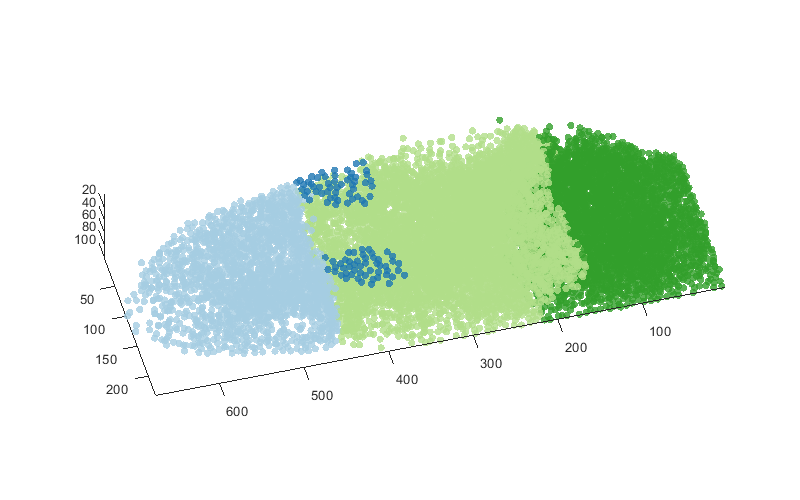

figure
set(gcf,  'Position',[50 50 800 500])
hold on
for k=[1,3,4,2]
index=toplot.xyzb(:,4)==k;
scatter3(toplot.xyzb(index,1),toplot.xyzb(index,2),toplot.xyzb(index,3),30,toplot.xyzb(index,4),'filled','o'), 
set (gca,'Zdir','reverse'),  set (gca,'Ydir','reverse'),  set (gca,'Xdir','reverse')
colormap (colorM), caxis([1 4])
alpha(.8)
end
axis image
%axis off
view (-15,45)

## PLOT THE HEATMAP OF THE REPRESENTATIVE WT EXAMPLE

generate figure A3

PLOT THE HEATMAP OF THE REPRESENTATIVE CTRL, dataset: 20220408_11_52_04_20220408volsmhctrlF01

load the data

load('X:\Manuscripts\Dgama etal 2024 smh\data\Figure 3\Panel A\20220408volsmhctrlF01Results_CLUSTERING.mat');

plot the heatmap

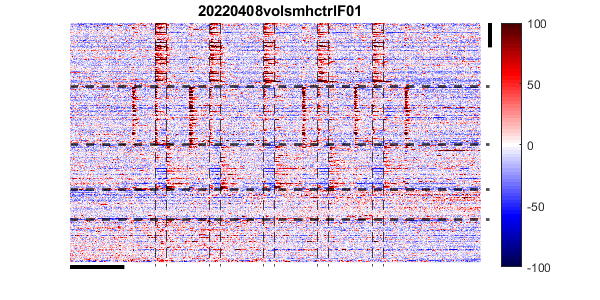

plot_heatmap(results)

## PLOT THE AVERAGE RESPONSE FOR ALL CELLS PER FISH

plot all response to all fishes

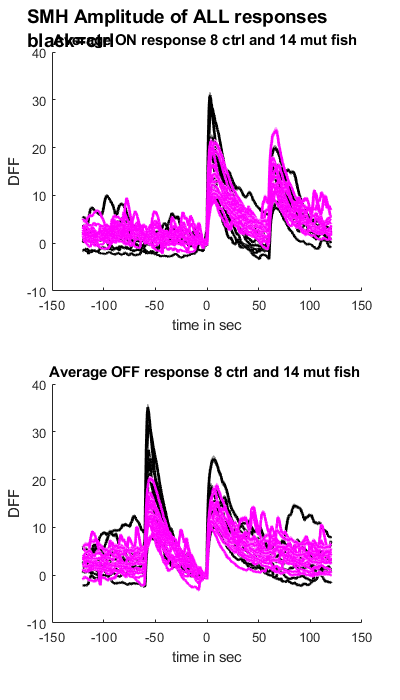

[averageON_ALL,averageOFF_ALL]=plot_responseALL_perfish(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg);

## PLOT THE AVERAGE RESPONSE FOR ALL CELLS FOR ALL FISH

generate panel D1-E1

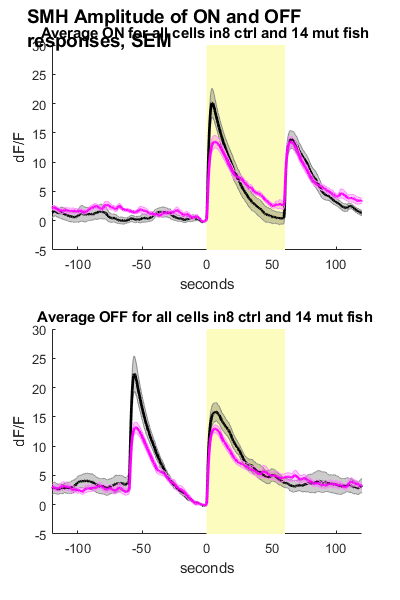

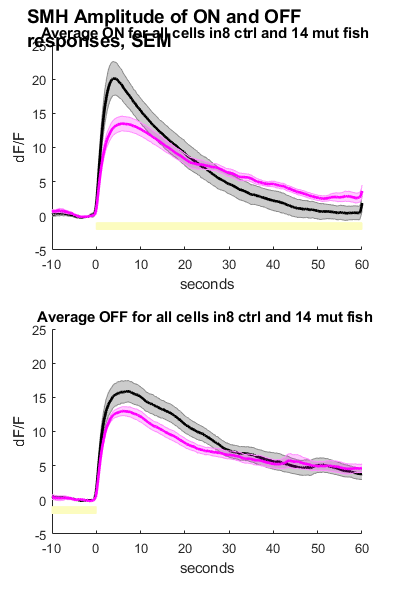

plot_responseALL_average(averageON_ALL,averageOFF_ALL,time,cfg);

## PLOT THE AVERAGE RESPONSE FOR ALL CELLS PER FISH

generate statistics for panel D1-E1

ans = '0.022228'

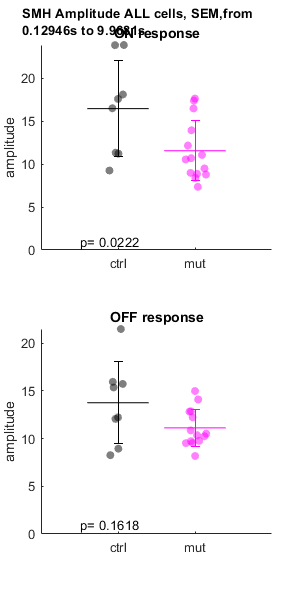

ans = '0.16176'

plot_scatterAll(averageON_ALL,averageOFF_ALL,ctrlON,ctrlOFF, mutON, mutOFF, time,cfg)

## CALCULATE % RESPONDING CELLS PER BRAIN REGION

generate panel D3-D4-E3-E4

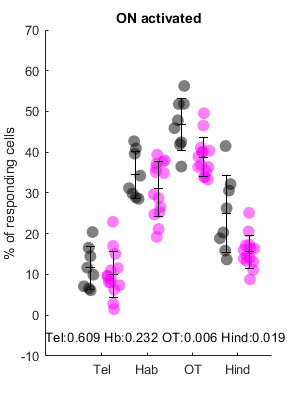

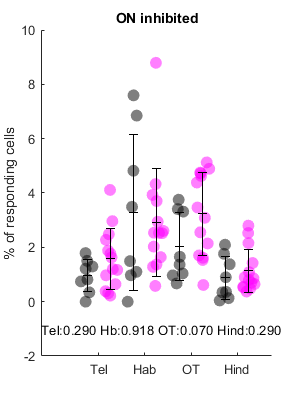

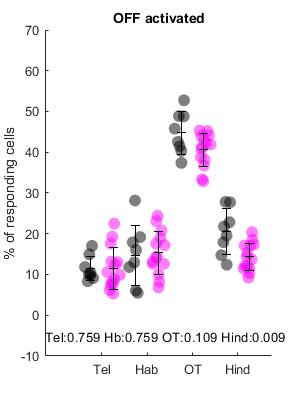

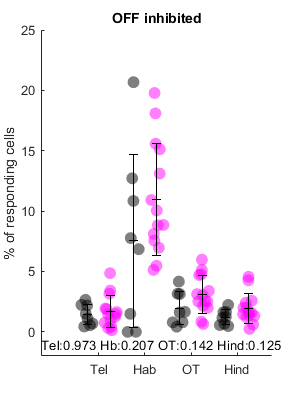

plot_response_perregion_v2(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

## CALCULATE AMPLITUDE PER BRAIN REGION

generate panel D2-E2

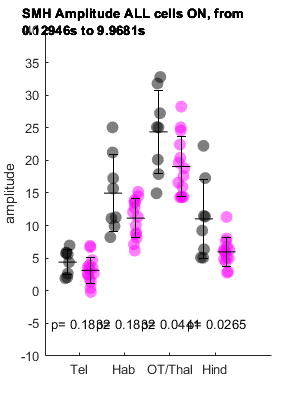

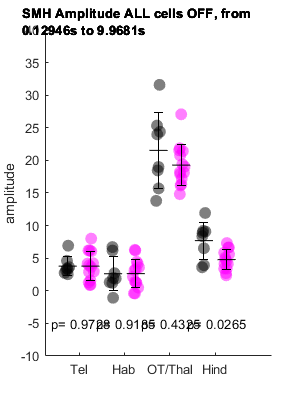

plot_amplitude_perregion(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

## CALCULATE % ON RESPONDING CELLS BASED ON location of  cells in x,y,z

chose ON dataset for the analysis

cfg.data=1;

Identify midline, by plotting OT and using ginput

% % ONLY NEEDS TO BE DONE ONCE
% identify_midline(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)
% % 
% % [midline_ctrl] = ginput() % select figure of ctrl
% [midline_mut] = ginput() % select figure of ctrl
% % copy values below
cfg.midline_ctrl = [352.102803738318	113.584829143338
370.917573872473	117.231685264341
456.775700934579	117.231685264341
391.951788491446	118.941323733066
391.355140186916	122.365919655480
369.634525660964	118.943096728054
418.118195956454	114.838067459285
423.403426791277	127.500154046618];
cfg.midline_mut = [376.401869158878	115.065469573066
374.183514774495	115.520273800628
444.626168224299	113.662232139248
266.757387247278	105.866776750983
426.401869158879	119.275181874520
393.856920684292	121.840388645827
447.429906542056	120.372432156119
304.276827371695	114.838067459285
422.313084112150	117.159232937755
400.388802488336	119.746625281139
387.1495            119.5109
401.788491446345	113.437603221977
377.803738317757	123.871136966938
467.573872472784	120.372432156118];

Location of the responding cells.

High Y axis value is left. In the scatter plots, left is anterior, right is poster, down is left, up is right

In teh shaded error bars are shown SEM

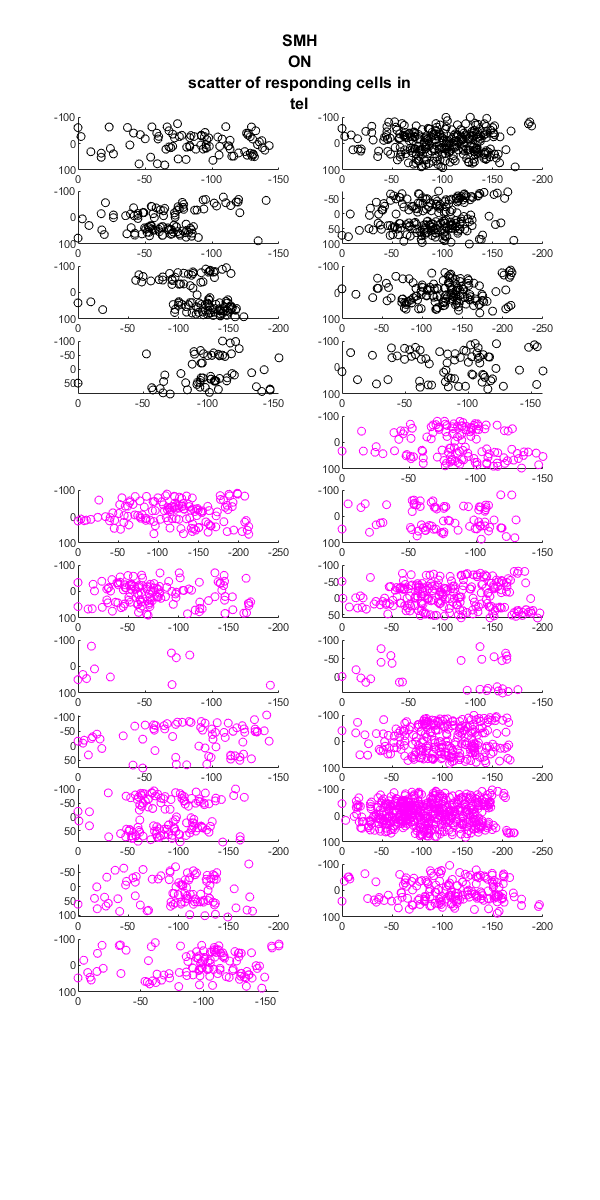

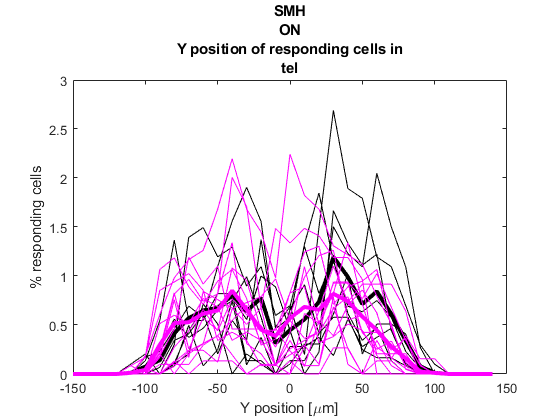

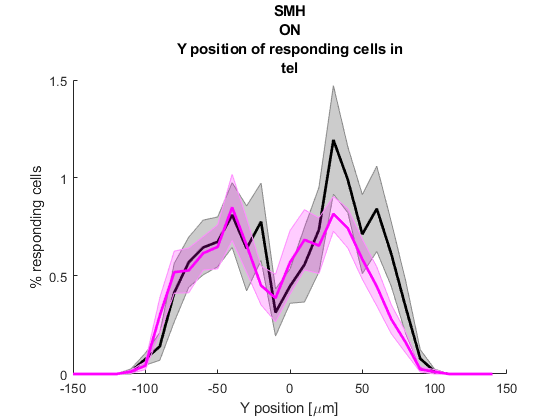

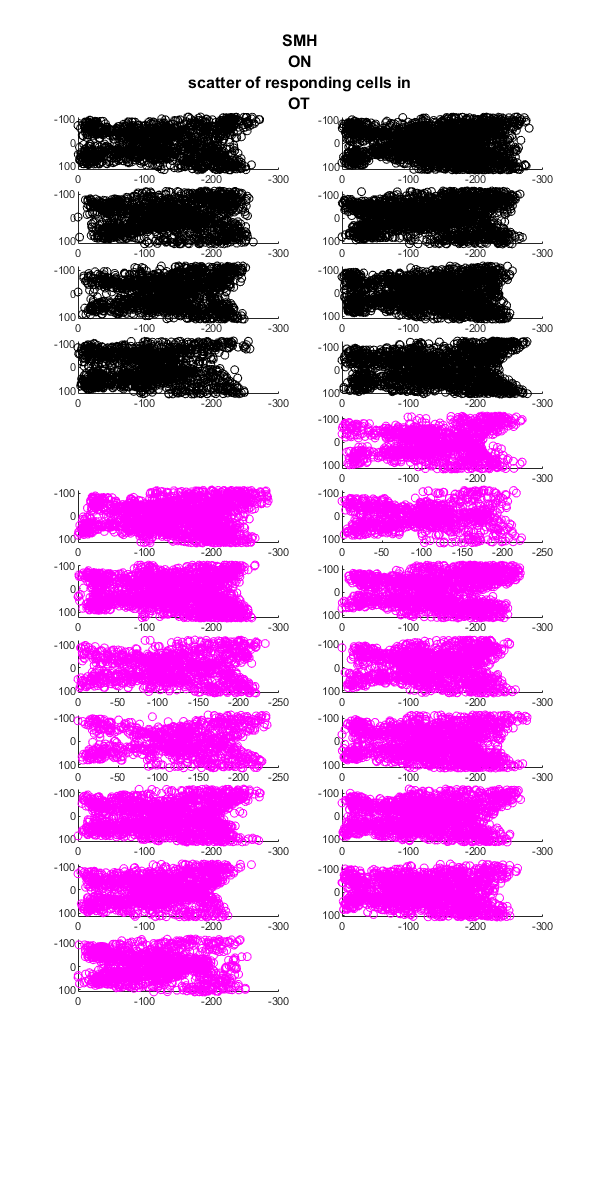

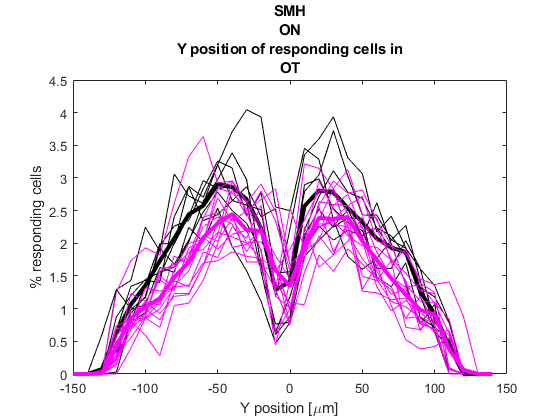

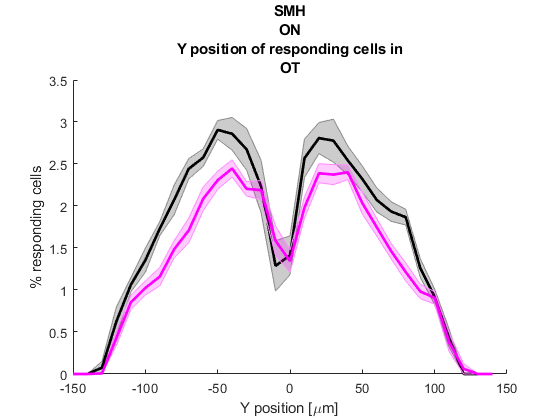

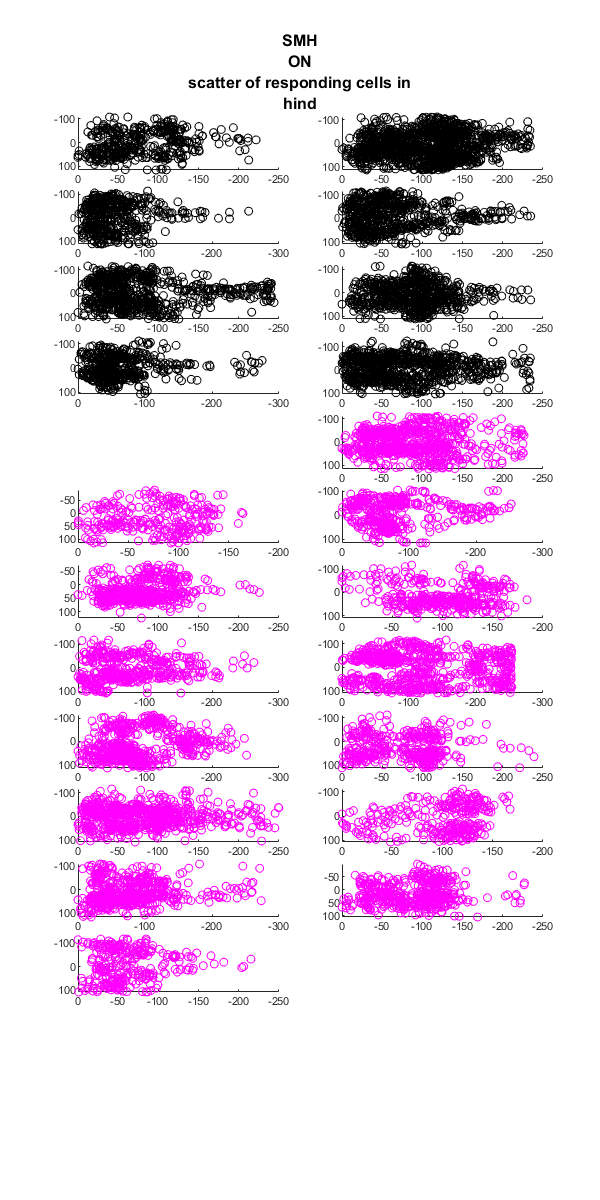

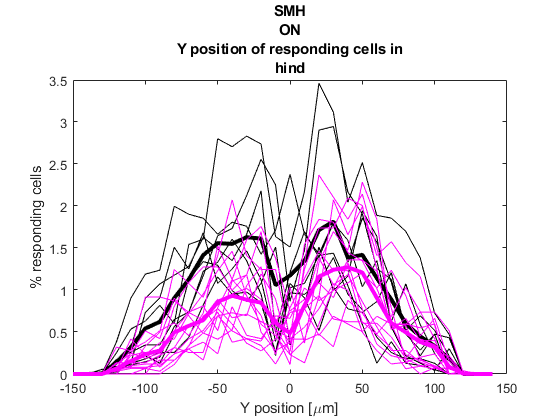

plot_respondingXYZ(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg);

## CALCULATE % OFF RESPONDING CELLS BASED ON location of  cells in x,y,z

Choose OFF dataset fror the analysis

cfg.data=2;

Location of the responding cells

plot_respondingXYZ(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

## NESTED FUNCTIONS

FUNCTION 0

function plot_heatmap(data)
% HEATMAP------------------------------------------------------------------
% plot the clustering with a bar for 5 min --------------------------------
% re-orderd the cluster so that cluster 1-2 is ON, cluster 3 is OFF, cluster
% 4 and 5 is not showing large activity
idx2=data.idx;
idx2(data.idx==4)=12;
idx2(data.idx==2)=13;
idx2(data.idx==5)=10;
idx2(data.idx==1)=11;
idx2(data.idx==3)=14;
% x scalebar is 5 min, y scalebar is 1000 neurons
cmap = seismic();
figure('Position', [100 100 600 300])
imagesc(sortrows(cat(2, idx2, data.DV_DFFaveragetime ))), hold on
colormap(cmap)
caxis([-100 100])
%colorbar
xline(data.cfg.TimeVector.ON,'k--','LineWidth',0.1)
xline(data.cfg.TimeVector.OFF,'k--','LineWidth',0.1)
yline(1+find(diff(sort(idx2))==1),'k--', 'LineWidth',2)
xlim([500 size(data.DV_DFFaveragetime,2)+200])
ylim([0 size(data.DV_DFFaveragetime,1)+200])
line([500 round(500+data.cfg.fps*60*5)], size(data.DV_DFFaveragetime,1)+[200 200],'Color','k','LineWidth', 3)
line(size(data.DV_DFFaveragetime,2)+[200 200], [0 1000],'Color','k','LineWidth',3)
box off
axis off
ax=gca;
set(ax,'XTick',[])
set(ax,'YTick',[])
%set(ax,'TickDir','out')
title(data.metadata.name)
colorbar
end

FUNCTION 1 TO PLOT THE AVERAGE DATA FOR ALL CELLS PER ANIMAL FOR ALL ANIMALS ON TOP OF EACH OTHER==========

function [averageON_ALL,averageOFF_ALL]=plot_responseALL_perfish(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

figure (30)
clf
set(gcf,  'Position',[100 100 400 700])
str= {[cfg.MutID ' Amplitude of ALL responses black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

% Average response ON
subplot(2,1,1)
for i=2:cfg.numCTRL+1  
shadedErrorBar(time,mean(ctrlON{i,6},1),std(ctrlON{i,6},[],1)/sqrt(size(ctrlON{i,6},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.ctrl(i-1,:)=mean(ctrlON{i,6},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time,mean(mutON{i,6},1),std(mutON{i,6},[],1)/sqrt(size(mutON{i,6},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageON_ALL.mut(i-1,:)=mean(mutON{i,6},1);
end
title(['Average ON response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])


% Average response OFF
subplot(2,1,2)
for i=2:cfg.numCTRL+1  
shadedErrorBar(time,mean(ctrlOFF{i,6},1),std(ctrlOFF{i,6},[],1)/sqrt(size(ctrlOFF{i,6},1)),'lineprops', 'k'), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFF_ALL.ctrl(i-1,:)=mean(ctrlOFF{i,6},1);
end
for i=2:cfg.numMUT+1
shadedErrorBar(time,mean(mutOFF{i,6},1),std(mutOFF{i,6},[],1)/sqrt(size(mutOFF{i,6},1)),'lineprops', cfg.Mutcolor), hold on
xlabel('time in sec')
ylabel('DFF')
averageOFF_ALL.mut(i-1,:)=mean(mutOFF{i,6},1);
end
title(['Average OFF response ' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])


end

% FUNCTION2 PLOT THE AVERAGE OF THE AVERAGE OF ALL CELLS FOR ALL ANIMALS ON TOP OF EACH OTHER==================

function plot_responseALL_average(averageON_ALL,averageOFF_ALL,time,cfg)

figure (40)
clf
set(gcf,  'Position',[100 100 400 600])
str= {[cfg.MutID ' Amplitude of ON and OFF responses, SEM']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,1,1)
rectangle('Position',[0 -8 60 70],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageON_ALL.ctrl,1),std(averageON_ALL.ctrl,[],1)/sqrt(size(averageON_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageON_ALL.mut,1),std(averageON_ALL.mut,[],1)/sqrt(size(averageON_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average ON for all cells in' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-5 30])
xlabel('seconds')
ylabel('dF/F')

subplot(2,1,2)
rectangle('Position',[0 -40 60 80],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageOFF_ALL.ctrl,1),std(averageOFF_ALL.ctrl,[],1)/sqrt(size(averageOFF_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageOFF_ALL.mut,1),std(averageOFF_ALL.mut,[],1)/sqrt(size(averageOFF_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average OFF for all cells in' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-120 120])
ylim([-5 30])
xlabel('seconds')
ylabel('dF/F')

figure (41)
clf
set(gcf,  'Position',[100 100 400 600])
str= {[cfg.MutID ' Amplitude of ON and OFF responses, SEM']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,1,1)
rectangle('Position',[0 -2 60 1],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageON_ALL.ctrl,1),std(averageON_ALL.ctrl,[],1)/sqrt(size(averageON_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageON_ALL.mut,1),std(averageON_ALL.mut,[],1)/sqrt(size(averageON_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average ON for all cells in' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-10 60])
ylim([-5 25])
xlabel('seconds')
ylabel('dF/F')

subplot(2,1,2)
rectangle('Position',[-10 -2 10 1],'FaceColor',[0.99 0.99 0.75], 'EdgeColor',[0.99 0.99 0.75]), hold on
shadedErrorBar(time,mean(averageOFF_ALL.ctrl,1),std(averageOFF_ALL.ctrl,[],1)/sqrt(size(averageOFF_ALL.ctrl,1)),'lineprops', 'k')
shadedErrorBar(time,mean(averageOFF_ALL.mut,1),std(averageOFF_ALL.mut,[],1)/sqrt(size(averageOFF_ALL.mut,1)),'lineprops', cfg.Mutcolor)
title(['Average OFF for all cells in' num2str(cfg.numCTRL) ' ctrl and ' num2str(cfg.numMUT) ' mut fish '])
xlim([-10 60])
ylim([-5 25])
xlabel('seconds')
ylabel('dF/F')

end

FUNCTION3 PLOT AVERAGE AMPLITUDE FOR 10SEC AFTER FOR RESPONDING CELLS

function plot_scatterAll(averageON_ALL,averageOFF_ALL,ctrlON,ctrlOFF, mutON, mutOFF, time,cfg)

% enter the frames. this is for 10sec
onset=465;
offset=503;

figure (51)
clf
set(gcf,  'Position',[100 100 300 600])
str= {[cfg.MutID ' Amplitude ALL cells, SEM,from ' num2str(time(onset)) 's to ' num2str(time(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,1,1)
toplotC=averageON_ALL.ctrl(:,onset:offset);
toplotM=averageON_ALL.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([0 Inf])
ylabel('amplitude')
text(0.5,1,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ON response')

num2str(ranksum(mean(toplotC,2),mean(toplotM,2)))
clear toplotC toplotM


subplot(2,1,2)
toplotC=averageOFF_ALL.ctrl(:,onset:offset);
toplotM=averageOFF_ALL.mut(:,onset:offset);
swarmchart(ones(cfg.numCTRL,1), mean(toplotC,2),'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar(1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart(2*ones(cfg.numMUT,1), mean(toplotM,2),cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color',cfg.Mutcolor)
xlim([0 3]), ylim([0 Inf])
ylabel('amplitude')
text(0.5,1,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1 2])
xticklabels({'ctrl','mut'})
title('OFF response')

num2str(ranksum(mean(toplotC,2),mean(toplotM,2)))
clear toplotC toplotM
end


FUNCTION 4 plots % responding cells per brain region

function plot_response_perregion(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

close all
%% calculate number of responding cells per region
NumCtrl=[];
NumMut=[];
jj=[1,4,2,3]; %reorder so that Hb is between Tel and OT, added 14.03.2023

% calculate responding cells per brain region
for k=1:cfg.numCTRL
for ik=1:4; %there are four brain region
    j=jj(ik);
NumCtrl.ON.activated(k,ik)=length(find(ctrlON{k+1, 4}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;  
NumCtrl.OFF.activated(k,ik)=length(find(ctrlOFF{k+1, 4}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;
NumCtrl.ON.inhibited(k,ik)=length(find(ctrlON{k+1, 5}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;
NumCtrl.OFF.inhibited(k,ik)=length(find(ctrlOFF{k+1, 5}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;

end
end

for k=1:cfg.numMUT
for ik=1:4; %there are four brain region
    j=jj(ik);
NumMut.ON.activated(k,ik)=length(find(mutON{k+1, 4}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.activated(k,ik)=length(find(mutOFF{k+1, 4}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;  
NumMut.ON.inhibited(k,ik)=length(find(mutON{k+1, 5}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.inhibited(k,ik)=length(find(mutOFF{k+1, 5}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;
end
end

figure (70),
clf
set(gcf,  'Position',[100 100 800 600])
str= {[cfg.MutID ' % responding cells per brain area black=ctrl']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',14, 'FontWeight', 'bold', 'LineStyle', 'none');

subplot(2,2,1)
toplotC=NumCtrl.ON.activated;
toplotM=NumMut.ON.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([0 5]), ylim([0 80])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON activated')
clear toplotC toplotM p
hold off

subplot(2,2,2)
toplotC=NumCtrl.ON.inhibited;
toplotM=NumMut.ON.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([0 5]), ylim([-1 10])
ylabel('% of responding cells')

for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON inhibited')
clear toplotC toplotM p
hold off


subplot(2,2,3)
toplotC=NumCtrl.OFF.activated;
toplotM=NumMut.OFF.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([0 5]), ylim([0 80])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF activated')
clear toplotC toplotM p
hold off


subplot(2,2,4)
toplotC=NumCtrl.OFF.inhibited;
toplotM=NumMut.OFF.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color',cfg.Mutcolor, 'Marker','_')
end
xlim([0 5]), ylim([-1 25])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF inhibited')
clear toplotC toplotM p
hold off
end

FUNCTION 5 plots % active cells per region

function plot_response_perregion_v2(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)
%% calculate number of responding cells per region
%close all
NumCtrl=[];
NumMut=[];
jj=[1,4,2,3]; %reorder so that Hb is between Tel and OT, added 14.03.2023

% calculate responding cells per brain region
for k=1:cfg.numCTRL
for ik=1:4; %there are four brain region
    j=jj(ik);
NumCtrl.ON.activated(k,ik)=length(find(ctrlON{k+1, 4}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;  
NumCtrl.OFF.activated(k,ik)=length(find(ctrlOFF{k+1, 4}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;
NumCtrl.ON.inhibited(k,ik)=length(find(ctrlON{k+1, 5}(:,4)==j))/sum(ctrlON{k+1, 7}(:,4)==j)*100;
NumCtrl.OFF.inhibited(k,ik)=length(find(ctrlOFF{k+1, 5}(:,4)==j))/sum(ctrlOFF{k+1, 7}(:,4)==j)*100;

end
end

for k=1:cfg.numMUT
for ik=1:4; %there are four brain region
    j=jj(ik);
NumMut.ON.activated(k,ik)=length(find(mutON{k+1, 4}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.activated(k,ik)=length(find(mutOFF{k+1, 4}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;  
NumMut.ON.inhibited(k,ik)=length(find(mutON{k+1, 5}(:,4)==j))/sum(mutON{k+1, 7}(:,4)==j)*100;  
NumMut.OFF.inhibited(k,ik)=length(find(mutOFF{k+1, 5}(:,4)==j))/sum(mutOFF{k+1, 7}(:,4)==j)*100;
end
end

figure (57),
clf
set(gcf,  'Position',[100 100 300 400])
toplotC=NumCtrl.ON.activated;
toplotM=NumMut.ON.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color','k', 'Marker','_')
end
xlim([0 5]), ylim([-10 70])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON activated')
clear toplotC toplotM p
hold off

figure (58)
clf
set(gcf,  'Position',[100 100 300 400])
str= {[cfg.MutID ' % ON inhibited']};
toplotC=NumCtrl.ON.inhibited;
toplotM=NumMut.ON.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color','k', 'Marker','_')
end
xlim([0 5]), ylim([-2 10])
ylabel('% of responding cells')

for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-1,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('ON inhibited')
clear toplotC toplotM p
hold off


figure (59)
clf
set(gcf,  'Position',[100 100 300 400])
str= {[cfg.MutID ' % OFF activated']};
toplotC=NumCtrl.OFF.activated;
toplotM=NumMut.OFF.activated;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color','k', 'Marker','_')
end
xlim([0 5]), ylim([-10 70])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-5,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF activated')
clear toplotC toplotM p
hold off


figure (60)
clf
set(gcf,  'Position',[100 100 300 400])
str= {[cfg.MutID ' % OFF inhibited']};
toplotC=NumCtrl.OFF.inhibited;
toplotM=NumMut.OFF.inhibited;
swarmchart(repmat([1 2 3 4], cfg.numCTRL,1), toplotC,80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii,mean(toplotC(:,ii)), std(toplotC(:,ii)),'Color','k', 'Marker','_')
end
swarmchart(repmat([1.5 2.5 3.5 4.5], cfg.numMUT,1), toplotM,80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
for ii=1:4
errorbar(ii+0.5,mean(toplotM(:,ii)), std(toplotM(:,ii)),'Color','k', 'Marker','_')
end
xlim([-0 5]), ylim([-2 25])
ylabel('% of responding cells')
for i=1:4
p(i)=ranksum(toplotC(:,i),toplotM(:,i));
end
text(0,-1,num2str(['Tel:' sprintf('%.3f',p(1))...
    ' Hb:' sprintf('%.3f',p(2)) ' OT:' sprintf('%.3f',p(3))...
    ' Hind:' sprintf('%.3f',p(4))]))
xticks([1.25 2.25 3.25 4.25])
xticklabels({'Tel', 'Hab','OT', 'Hind'})
title('OFF inhibited')
clear toplotC toplotM p
hold off
end

FUNCTION calculate amplitude per brain region

function plot_amplitude_perregion(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

onset=465;
offset=503;

jj=[1,4,2,3]; %reorder so that Hb is between Tel and OT, added 14.03.2023


figure (61)
clf
for k=1:4
    j=jj(k);
set(gcf,  'Position',[100 100 300 400])
str= {[cfg.MutID ' Amplitude ALL cells ON, from ' num2str(time(onset)) 's to ' num2str(time(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

for i=1:cfg.numCTRL 
matrixC(i,:)=mean(ctrlON{i+1,6}(ctrlON{i+1,7}(:,4)==j,:),1);
end
for i=1:cfg.numMUT 
matrixM(i,:)=mean(mutON{i+1,6}(mutON{i+1,7}(:,4)==j,:),1);
end
toplotC=matrixC(:,onset:offset);
toplotM=matrixM(:,onset:offset);
swarmchart((2*k-2)+ones(cfg.numCTRL,1), mean(toplotC,2),80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((2*k-2)+[0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar((2*k-2)+1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart((2*k-2)+2*ones(cfg.numMUT,1), mean(toplotM,2),80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((2*k-2)+[1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color','k')
errorbar((2*k-2)+2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color','k')
%xlim([0 3]), 
ylim([-10 40])
ylabel('amplitude')
text((2*k-2)+0.25,-5,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1.5 3.5 5.5 7.5])
xticklabels({'Tel', 'Hab','OT/Thal', 'Hind'})
%title([cfg.brainRegion(k,:) 'ON response'])
clear toplotC toplotM matrixC matrixM
end

figure (62)
clf
for k=1:4
    j=jj(k);
set(gcf,  'Position',[100 100 300 400])
str= {[cfg.MutID ' Amplitude ALL cells OFF, from ' num2str(time(onset)) 's to ' num2str(time(offset)) 's']};
annotation('textbox',[0.05 0.95 0.9 0.05],'String',str, 'FontSize',10, 'FontWeight', 'bold', 'LineStyle', 'none');

for i=1:cfg.numCTRL 
matrixC(i,:)=mean(ctrlOFF{i+1,6}(ctrlOFF{i+1,7}(:,4)==j,:),1);
end
for i=1:cfg.numMUT 
matrixM(i,:)=mean(mutOFF{i+1,6}(mutOFF{i+1,7}(:,4)==j,:),1);
end
toplotC=matrixC(:,onset:offset);
toplotM=matrixM(:,onset:offset);
swarmchart((2*k-2)+ones(cfg.numCTRL,1), mean(toplotC,2),80,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((2*k-2)+[0.6 1.4], repmat(mean(mean(toplotC,2)),1,2),'Color','k')
errorbar((2*k-2)+1,mean(mean(toplotC,2)), std(mean(toplotC,2)),'Color','k')
swarmchart((2*k-2)+2*ones(cfg.numMUT,1), mean(toplotM,2),80,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line((2*k-2)+[1.6 2.4], repmat(mean(mean(toplotM,2)),1,2),'Color','k')
errorbar((2*k-2)+2,mean(mean(toplotM,2)), std(mean(toplotM,2)),'Color','k')
%xlim([0 3]), 
ylim([-10 40])
ylabel('amplitude')
text((2*k-2)+0.25,-5,['p= '...
    num2str(ranksum(mean(toplotC,2),mean(toplotM,2)),'%.4f')]);
xticks([1.5 3.5 5.5 7.5])
xticklabels({'Tel', 'Hab','OT/Thal', 'Hind'})
%title([cfg.brainRegion(k,:) 'ON response'])
clear toplotC toplotM matrixC matrixM
end
%close all
end

FUNCTION IDENTIFY MIDLINE USING GINPUT

function identify_midline(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

%% plot the scatter of the location of all responding cells
j=2; %this is OT only
% figure, 
% suptitle('ctrl ON activated')
% for k=1:cfg.numCTRL
% ID=find(ctrlON{k+1, 4}(:,4)==j);
% subplot(ceil(size(ctrlON,1)/2),2,k)
% scatter(ctrlON{k+1, 4}(ID,1),ctrlON{k+1, 4}(ID,2))
% end


figure, 
suptitle('mut ON activated')
for k=1:cfg.numMUT 
ID=find(mutON{k+1, 4}(:,4)==j);
subplot(ceil(size(mutON,1)/2),2,k)
scatter(mutON{k+1, 4}(ID,1),mutON{k+1, 4}(ID,2))
end
end


FUNCTION PLOT % ACTIVE CELLS ACCORDING TO X,Y,Z

function plot_respondingXYZ(ctrlON,ctrlOFF,mutON,mutOFF,time,cfg)

% if you want to plot ON response, 
if cfg.data==1
mut=mutON;
ctrl=ctrlON;
TEXT='ON';
elseif  cfg.data==2
mut=mutOFF;
ctrl=ctrlOFF;
TEXT='OFF';
end

for j=1:4; %this decide on brain region

clear edges N_ctrlN N_mutN N_ctrl N_mut edges_mut edges_ctrl
% plot the scatter of the location of all responding cells
figure , 
clf
set(gcf,  'Position',[100 100 600 1200])
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,k)
scatter(ctrl{k+1, 4}(ID,1)-max(ctrl{k+1, 4}(ID,1)),ctrl{k+1, 4}(ID,2)-cfg.midline_ctrl(k,2),'k'), set (gca,'Ydir','reverse'),  set (gca,'Xdir','reverse')
end
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
subplot(ceil(size(ctrl,1)/2)+ceil(size(mut,1)/2),2,size(ctrl,1)+k)
scatter(mut{k+1, 4}(ID,1)-max(mut{k+1, 4}(ID,1)),mut{k+1, 4}(ID,2)-cfg.midline_mut(k,2),cfg.Mutcolor), set (gca,'Ydir','reverse'),  set (gca,'Xdir','reverse')
end
suptitle([cfg.MutID, TEXT ' scatter of responding cells in ' ,cfg.label(j)])

% calculate the position in the width
edges=[-150:10:150];
for k=1:cfg.numMUT
ID=find(mut{k+1, 4}(:,4)==j);
[N_mut(k,:),edges_mut(k,:)] = histcounts(mut{k+1, 4}(ID,2)-cfg.midline_mut(k,2),edges);%,'Normalization', 'probability');
N_mutN(k,:)=100*N_mut(k,:)/sum(mut{k+1, 7}(:,4)==j); % normalize to number of cell per brain region
clear ID
end
for k=1:cfg.numCTRL
ID=find(ctrl{k+1, 4}(:,4)==j);
[N_ctrl(k,:),edges_ctrl(k,:)] = histcounts(ctrl{k+1, 4}(ID,2)-cfg.midline_ctrl(k,2),edges);%,'Normalization', 'probability');
N_ctrlN(k,:)=100*N_ctrl(k,:)/sum(ctrl{k+1, 7}(:,4)==j);% normalize to number of cell per brain region
clear ID
end
%
figure, 
plot(edges(1:end-1),N_ctrlN.','k'), hold on, plot(edges(1:end-1),mean(N_ctrlN,1),'k','LineWidth',3), 
plot(edges(1:end-1),N_mutN.',cfg.Mutcolor),plot(edges(1:end-1),mean(N_mutN,1),cfg.Mutcolor,'LineWidth',3)
xlabel('Y position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Y position of responding cells in ' ,cfg.label(j)])

figure
shadedErrorBar(edges(1:end-1),mean(N_ctrlN,1),std(N_ctrlN,[],1)/sqrt(size(N_ctrlN,1)),'lineprops', 'k'), hold on, 
shadedErrorBar(edges(1:end-1),mean(N_mutN,1),std(N_mutN,[],1)/sqrt(size(N_mutN,1)),'lineprops', cfg.Mutcolor)
xlabel('Y position [\mum]')
ylabel('% responding cells')
title([cfg.MutID, TEXT ' Y position of responding cells in ' cfg.label(j)])


end
end


function c=seismic()
c = [
    0.0, 0.0, 0.3;
    0.0, 0.0, 0.35;
    0.0, 0.0, 0.4;
    0.0, 0.0, 0.45;
    0.0, 0.0, 0.5;
    0.0, 0.0, 0.55;
    0.0, 0.0, 0.6;
    0.0, 0.0, 0.65;
    0.0, 0.0, 0.7;
    0.0, 0.0, 0.75;
    0.0, 0.0, 0.8;
    0.0, 0.0, 0.85;
    0.0, 0.0, 0.9;
    0.0, 0.0, 0.95;
    0.0, 0.0, 1.0;
    0.05, 0.05, 1.0;
    0.1, 0.1, 1.0;
    0.15, 0.15, 1.0;
    0.2, 0.2, 1.0;
    0.25, 0.25, 1.0;
    0.3, 0.3, 1.0;
    0.35, 0.35, 1.0;
    0.4, 0.4, 1.0;
    0.45, 0.45, 1.0;
    0.5, 0.5, 1.0;
    0.55, 0.55, 1.0;
    0.6, 0.6, 1.0;
    0.65, 0.65, 1.0;
    0.7, 0.7, 1.0;
    0.75, 0.75, 1.0;
    0.8, 0.8, 1.0;
    0.85, 0.85, 1.0;
    0.9, 0.9, 1.0;
    0.95, 0.95, 1.0;
    1.0, 1.0, 1.0;
    1.0, 0.95, 0.95;
    1.0, 0.9, 0.9;
    1.0, 0.85, 0.85;
    1.0, 0.8, 0.8;
    1.0, 0.75, 0.75;
    1.0, 0.7, 0.7;
    1.0, 0.65, 0.65;
    1.0, 0.6, 0.6;
    1.0, 0.55, 0.55;
    1.0, 0.5, 0.5;
    1.0, 0.45, 0.45;
    1.0, 0.4, 0.4;
    1.0, 0.35, 0.35;
    1.0, 0.3, 0.3;
    1.0, 0.25, 0.25;
    1.0, 0.2, 0.2;
    1.0, 0.15, 0.15;
    1.0, 0.1, 0.1;
    1.0, 0.05, 0.05;
    1.0, 0.0, 0.0;
    0.95, 0.0, 0.0;
    0.9, 0.0, 0.0;
    0.85, 0.0, 0.0;
    0.8, 0.0, 0.0;
    0.75, 0.0, 0.0;
    0.7, 0.0, 0.0;
    0.65, 0.0, 0.0;
    0.6, 0.0, 0.0;
    0.55, 0.0, 0.0;
    0.5, 0.0, 0.0;
    0.45, 0.0, 0.0;
    0.4, 0.0, 0.0;
    0.35, 0.0, 0.0;
    0.3, 0.0, 0.0;
];
end